# 9.2 a)

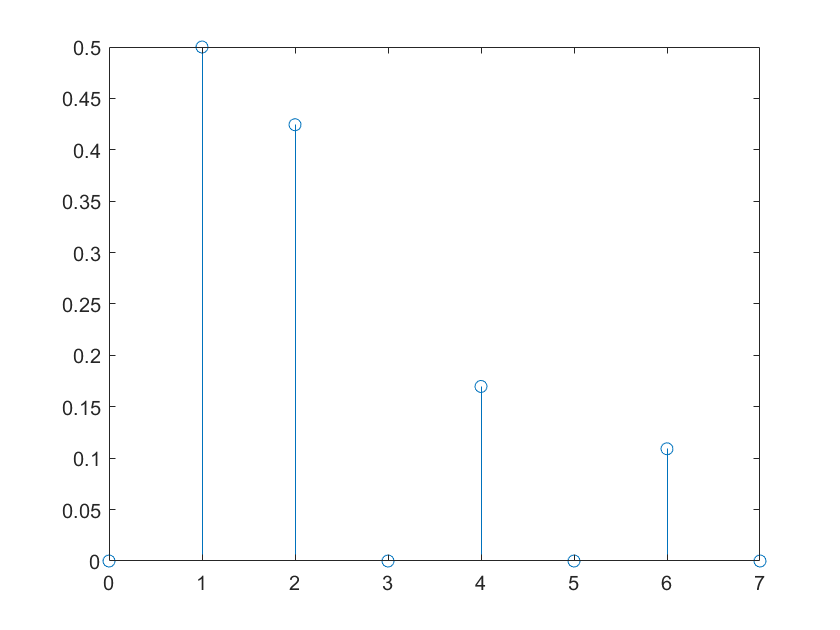

clear;
syms t f n t0;
T=2*pi;
tao_2=pi;
Nf=7;
Nn=6;
f = cos(t)*heaviside(t);

A0=int(f,t,-tao_2,T-tao_2)/T;
As=int(f*2*cos(2*pi*n*t/T)/T,t,-tao_2,T-tao_2);
Bs=int(f*2*sin(2*pi*n*t/T)/T,t,-tao_2,T-tao_2);
Fn=(As-1i*Bs)/2;
A(1)=double(vpa(A0,Nn));

for k=1:Nf
     A(k+1)=double(vpa(subs(As,n,k),Nn));
     B(k+1)=double(vpa(subs(Bs,n,k),Nn));
end

Fs(1)=A(1);
Fs(2:Nf+1)=abs(A(2:Nf+1)-1i.*B(2:Nf+1));
Ns=0:Nf;
stem(Ns,Fs);

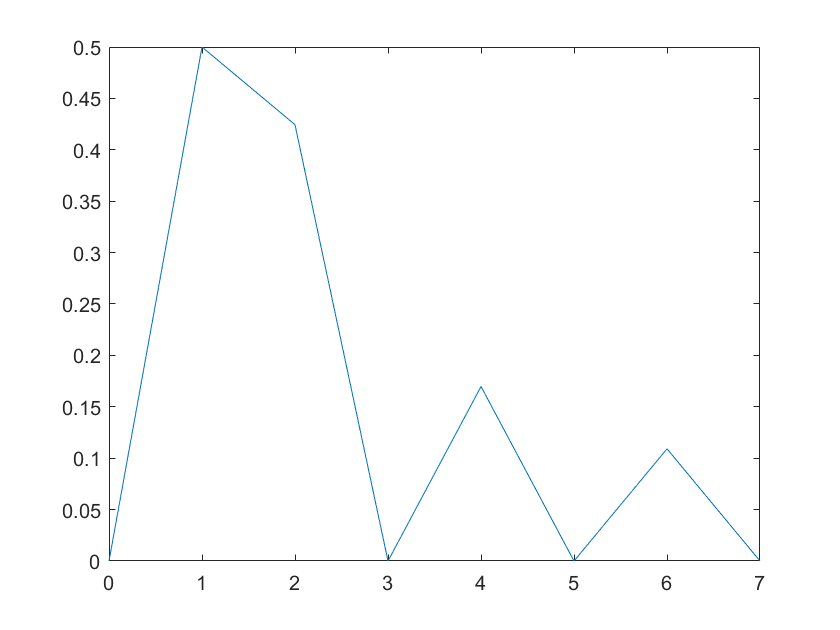

plot(Ns,Fs);